# Lab 5: Graph Matching, Part 2 (MA438)

## Recall: Graphs in MATLAB

In Lab 4, we learned several ways to construct a graph in MATLAB. In this session, we'll start by constructing our own graph, with a known matching of maximal cardinality. 

We'll start by making a graph on 8 vertices, with 4 edges, and 4 components.

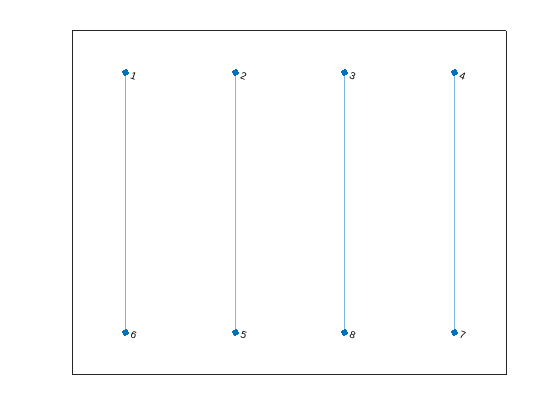

clear;
G = graph();
G=G.addedge(1,6);
G=G.addedge(2,5);
G=G.addedge(3,8);
G=G.addedge(4,7);
plot(G)

Next, we'll add some more edges. We'll make sure the graph is bipartite, by only adding edges between odd/even pairs. Note the resulting graph will always have the above matching.

We'll added the edges using two vectors, $s$ and $t$, so the edges will be between $s(i)$ and $t(i)$. If all the entries in $s$ are in $\{1,2,3,4\}$, and those in $t$ are in $\{5,6,7,8\}$, then the graph will be bipartite.

s = [1 2 3 1 4]

s =      1     2     3     1     4


t = [5 6 6 7 8]

t =      5     6     6     7     8


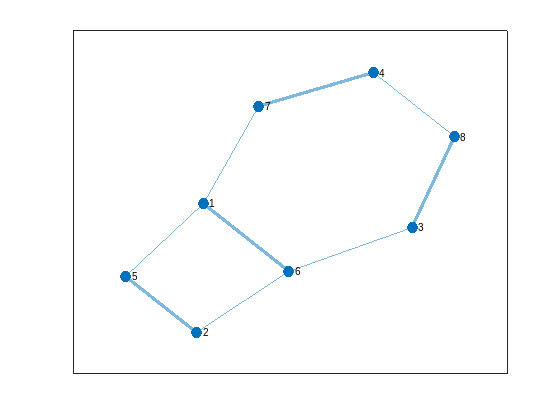

H = G.addedge(s,t);
h = plot(H);
highlight(h,G)

## The Matching Algorithm: Step 1

We'll start by pretending that we don't have a maximal matching for $H$. So we start with a minimal one: just a single edge. Any will do, but we'll use the edge $\{1,6\}$.

M = graph();
M = addnode(M, 8) % So M has same number of node as as H

M =   graph with properties:

    Edges: [0×1 table]
    Nodes: [8×0 table]

M = addedge(M, 1, 6)

M =   graph with properties:

    Edges: [1×1 table]
    Nodes: [8×0 table]

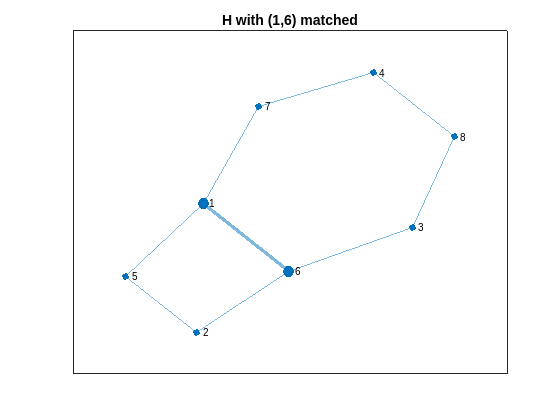

h = plot(H); title("H with (1,6) matched")
highlight(h, M)

Let's try to find larger one. First we need to make a directed graph, with edges between vertices if they are in the matching.

We start with an empty graph, $D$, on 8 vertices. Then, for every edge $e=\{e(1),e(2)\}$ in $H$ we'll add the directed edge $(e(1),e(2))$ to $H$ if it is also in $M$. Otherwise we add the edge $(e(2),e(1))$.

Some features of MATLAB's graph obect  that we'll use:

- If `G` is a graph, then `G.numedges` is the number of edges in `G`.

- `G.Edges` returns a "table" representing the edges. Since we haven't used tables, we'll access the associated $n \times 2$ matrix, where  `n=G.numedges`

- `Row `$i$ of this matrix contains the start end nodes of Edge $i$ of `G`.

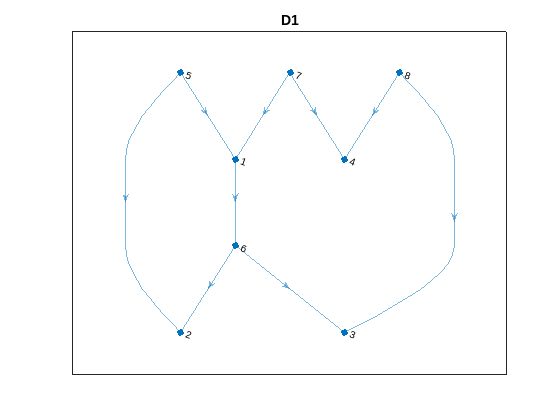

D1 = digraph();
D1 = D1.addnode(8);
% Iterate over the edges of H
n = H.numedges;
for i = 1:n
   e = H.Edges.EndNodes(i,:);
   if (findedge(M, e(1), e(2))) % is (e(1),e(2)) in matching?
      D1 = D1.addedge(e(1), e(2));
   else
      D1 = D1.addedge(e(2), e(1));
   end
end
plot(D1); title("D1")

Now we need to find a path in $D_1$ of length 3. Then we'll make a new subgraph of $H$ with the 1st and 3rd edges from that path. We can do this by looking at the distance matrix for $D_$:

distances(D1)

ans =      0     2     2   Inf   Inf     1   Inf   Inf
   Inf     0   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf     0   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf     0   Inf   Inf   Inf   Inf
     1     1     3   Inf     0     2   Inf   Inf
   Inf     1     1   Inf   Inf     0   Inf   Inf
     1     3     3     1   Inf     2     0   Inf
   Inf   Inf     1     1   Inf   Inf   Inf     0


We should be able to spot several of length 3. We can use the `find()` function to locate which entries are 3. 

[i,j]=find(distances(D1)==3,1) % find the i,j values of the first '3' entry

i = 7

j = 2

Next find the path between these. The `allpaths() `function can be used for this. Usually, it returns all possible paths of length between two given vertices. You can also specify:

- The maximum number of paths to find. We only need 1, so we'll set '`MaxNumPaths`' to 1.

- The mininum length of each path. Since we what only paths of length 3, we'll set '`MinPathLength`' to 3.

- For the same reason, we'll set '`MaxPathLength`' to 3 too.

p = allpaths(D1, i, j, 'MinPathLength',3, 'MaxPathLength',3)

p = 1×1 cell array
    {[7 1 6 2]}

But there is one further complication. `allpaths()` returns something called a cell array. Roughly, it is a matrix that can have different numbers of elements in each row (sometimes called a "ragged array"). We'll just convert it to a vector:

p = cell2mat(p)

p =      7     1     6     2


Now the vector p contains the vertex list for the path. We'll add every second one to $M$.

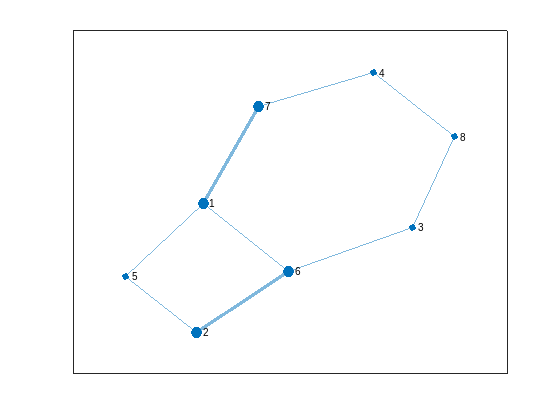

M = graph();
M = addnode(M, 8);
M = addedge(M, p(1), p(2));
M = addedge(M, p(3), p(4));
h = plot(H);
highlight(h, M)

## Step 2

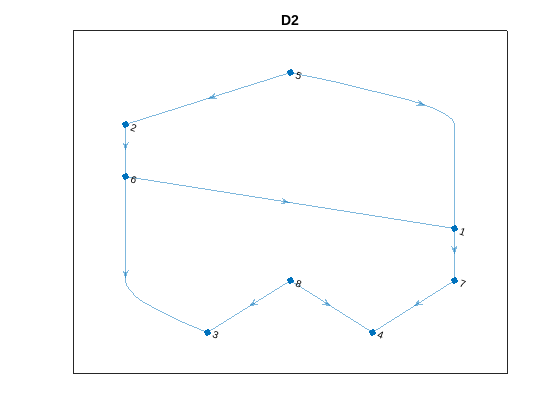

D2 = digraph();
D2 = D2.addnode(8);
% Iterate over the edges of H
for i = 1:H.numedges
   e = H.Edges.EndNodes(i,:);
   if (findedge(M,e(1),e(2)))
      D2 = D2.addedge(e(1),e(2));
   else
      D2 = D2.addedge(e(2),e(1));
   end
end
plot(D2); title("D2")

Make a new matching from this. 

This time, however, we can't use the `distances()` function. If you look at the graph, then you'll see that there is a path of length 5: [5,2,6,1,7,4]. However, there is another, shorter path between the same two vertices, and `distances()` only computes shortest paths. 

Instead, we'll use a trick we learned last week: if $A$ is the adjacency matrix of $G$, then then $(A^k)_{i,j}$ is the number of paths of length $k$ from $i$ to $j$. 

A = D2.adjacency;
[i,j]=find (A^5 >0,1)

i = 5

j = 4

Now carry on as before.

p = cell2mat(allpaths(D2, i, j, 'MinPathLength',5, 'MaxPathLength',5))

p =      5     2     6     1     7     4


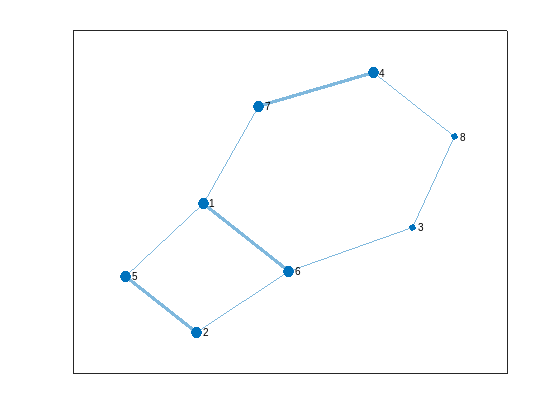

M = graph();
M = addnode(M, 8);
M = addedge(M, p(1), p(2));
M = addedge(M, p(3), p(4));
M = addedge(M, p(5), p(6));
h = plot(H);
highlight(h, M)

Now we have found a matching in the graph with 3 edges. We know we can do better...

## Iterating

One more iteration of the algorithm should complete the matching. 

Add your code here to preform that.

## Bonus!

The code you've run is rather repetative. Can you wrrite a shorter, more general version that (for example) uses a while() loop to re-run the repetative code. If you try that:

- Think about what, exactly, changes between loops.

- How would you know if you are finished?